QT_real=QTn(:,51:100);
RR_real=RRn(:,51:100);

QTm_re=mean(QT_real);
RRm_re=mean(RR_real);

QTv_re=std(QT_real);
RRv_re=std(RR_real);

QTvi_re=QTVin(51:100);

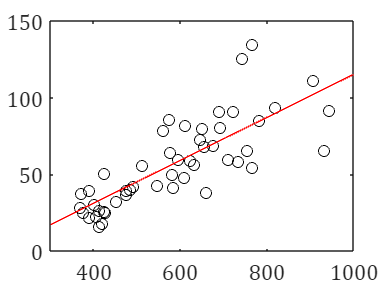

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
xx=RRm_re(ii1);yy=RRv_re(ii1);
xx(46:50)=mean(RRnin(:,6:10));
yy(46:50)=std(RRnin(:,6:10));
plot(xx,yy,'ok')
hold on
p=polyfit(xx,yy,1);
xx2=300:1:1000;
plot(xx2,xx2*p(1)+p(2),'r')
xlim([300 1000])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

[R,P] = corrcoef(xx,yy)

R =     1.0000    0.7859
    0.7859    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


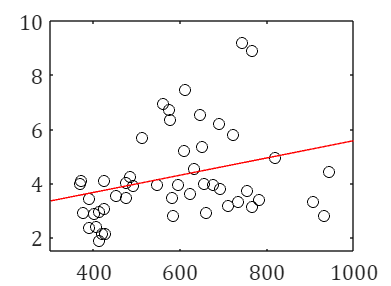

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
xx=RRm_re(ii1);yy=QTv_re(ii1);
%[R,P] = corrcoef(xx,yy)
xx(46:50)=mean(RRnin(:,6:10));
yy(46:50)=std(QTnin(:,6:10));
%plot(RRm_re(ii1),QTv_re(ii1),'ok')
plot(xx,yy,'ok')
hold on
p=polyfit(xx,yy,1);
xx2=300:1:1000;
plot(xx2,xx2*p(1)+p(2),'r')
xlim([300 1000])
ylim([1.5 10])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

[R,P] = corrcoef(xx,yy)

R =     1.0000    0.2978
    0.2978    1.0000


P =     1.0000    0.0357
    0.0357    1.0000


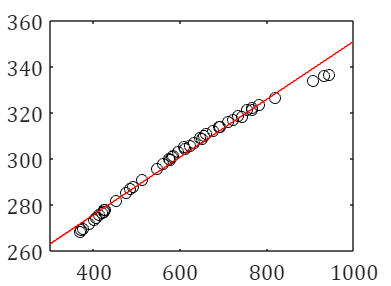

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
xx=RRm_re(ii1);yy=QTm_re(ii1);
%[R,P] = corrcoef(xx,yy)
xx(46:50)=mean(RRnin(:,6:10));
yy(46:50)=mean(QTnin(:,6:10));
%plot(RRm_re(ii1),QTv_re(ii1),'ok')
plot(xx,yy,'ok')
hold on
p=polyfit(xx,yy,1);
xx2=300:1:1000;
plot(xx2,xx2*p(1)+p(2),'r')
xlim([300 1000])
%ylim([1.5 10])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

[R,P] = corrcoef(xx,yy)

R =     1.0000    0.9923
    0.9923    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


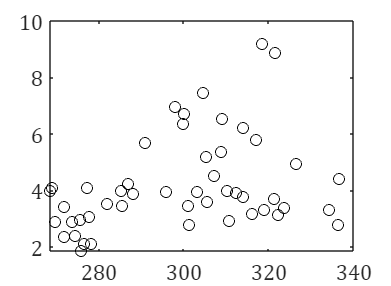

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
xx=QTm_re(ii1);yy=QTv_re(ii1);
%[R,P] = corrcoef(xx,yy)
xx(46:50)=mean(QTnin(:,6:10));
yy(46:50)=std(QTnin(:,6:10));
%plot(RRm_re(ii1),QTv_re(ii1),'ok')
plot(xx,yy,'ok')
hold on
p=polyfit(xx,yy,1);
xx2=300:1:1000;
%plot(xx2,xx2*p(1)+p(2),'r')
%xlim([300 1000])
%ylim([1.5 10])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

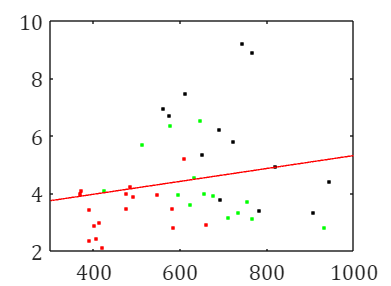

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
rrm_re=RRm_re(ii1);qtv_re=QTv_re(ii1);
rrv_re=RRv_re(ii1);

plot(rrm_re(rrv_re<150),qtv_re(rrv_re<150),'.k')
hold on
plot(rrm_re(rrv_re<75),qtv_re(rrv_re<75),'.g')
plot(rrm_re(rrv_re<50),qtv_re(rrv_re<50),'.r')
xx=RRm_re(ii1);yy=QTv_re(ii1);
p=polyfit(xx,yy,1);
xx2=300:1:1000;
plot(xx2,xx2*p(1)+p(2),'r')
xlim([300 1000])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

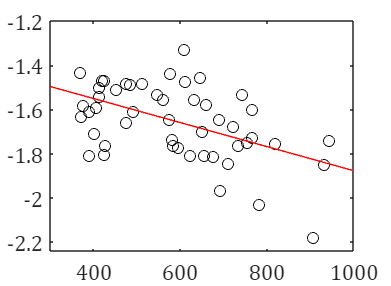

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
xx=RRm_re(ii1);yy=QTvi_re(ii1);
xx(46:50)=mean(RRnin(:,6:10));
yy(46:50)=QTVinin(:,6:10);
%plot(RRm_re(ii1),QTvi_re(ii1),'ok')
plot(xx,yy,'ok')
hold on
p=polyfit(xx,yy,1);
xx2=300:1:1000;
plot(xx2,xx2*p(1)+p(2),'r')
xlim([300 1000])
ylim([-2.24 -1.2])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

[R,P] = corrcoef(xx,yy)

R =     1.0000   -0.5020
   -0.5020    1.0000


P =     1.0000    0.0002
    0.0002    1.0000


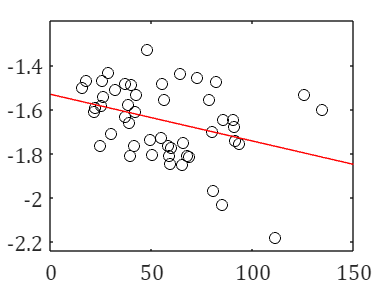

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
xx=RRv_re(ii1);yy=QTvi_re(ii1);
xx(46:50)=std(RRnin(:,6:10));
yy(46:50)=QTVinin(:,6:10);
%plot(RRm_re(ii1),QTvi_re(ii1),'ok')
plot(xx,yy,'ok')
hold on
p=polyfit(xx,yy,1);
xx2=0:1:150;
plot(xx2,xx2*p(1)+p(2),'r')
%xlim([300 1000])
ylim([-2.24 -1.2])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

[R,P] = corrcoef(xx,yy)

R =     1.0000   -0.3476
   -0.3476    1.0000


P =     1.0000    0.0134
    0.0134    1.0000


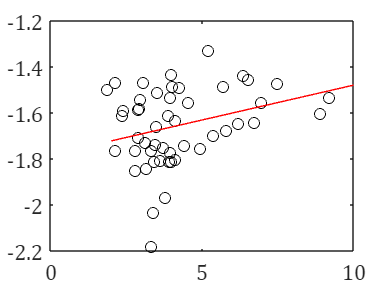

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
xx=QTv_re(ii1);yy=QTvi_re(ii1);
%[R,P] = corrcoef(xx,yy)
xx(46:50)=std(QTnin(:,6:10));
yy(46:50)=QTVinin(:,6:10);
%plot(RRm_re(ii1),QTv_re(ii1),'ok')
plot(xx,yy,'ok')
hold on
p=polyfit(xx,yy,1);
xx2=2:1:10;
plot(xx2,xx2*p(1)+p(2),'r')
%xlim([300 1000])
%ylim([1.5 10])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

[R,P] = corrcoef(xx,yy)

R =     1.0000    0.2995
    0.2995    1.0000


P =     1.0000    0.0346
    0.0346    1.0000


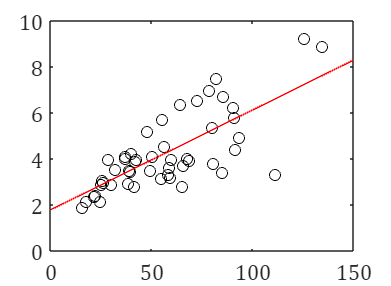

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
xx=RRv_re(ii1);yy=QTv_re(ii1);
xx(46:50)=std(RRnin(:,6:10));
yy(46:50)=std(QTnin(:,6:10));
%plot(RRv_re(ii1),QTv_re(ii1),'ok')
plot(xx,yy,'ok')
hold on
xx=RRv_re(ii1);yy=QTv_re(ii1);
p=polyfit(xx,yy,1);
xx2=0:1:150;
plot(xx2,xx2*p(1)+p(2),'r')
xlim([0 150])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

[R,P] = corrcoef(xx,yy)

R =     1.0000    0.7039
    0.7039    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


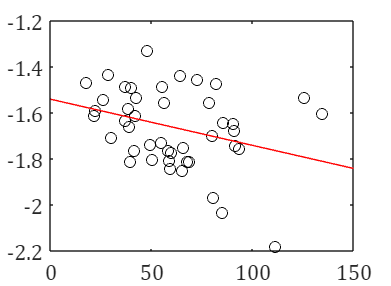

figure
ii1=1:1:50;ii1([3,32,35,39,47])=[];
plot(RRv_re(ii1),QTvi_re(ii1),'ok')
hold on
xx=RRv_re(ii1);yy=QTvi_re(ii1);
p=polyfit(xx,yy,1);
xx2=0:1:150;
plot(xx2,xx2*p(1)+p(2),'r')
xlim([0 150])
set (gcf,'Position',[500,100,300,220])
set(gca,'linewidth',1,'Box','on','FontName','Cambria Math','FontSize',12)

xx3(:,1)=RRm_re(ii1);
xx3(:,2)=RRv_re(ii1);

xx3(:,3)=QTv_re(ii1);
xx3(:,4)=QTvi_re(ii1);

save("real_rr_QTV_QTVi",'xx3')

QT_real=QTn(:,51:100);
RR_real=RRn(:,51:100);

QTm_re=mean(QT_real);
RRm_re=mean(RR_real);

QTv_re=std(QT_real);
RRv_re=std(RR_real);

QTvi_re=QTVi(51:100);

QT_gaus=QTn(:,1:51);
RR_gaus=RRn(:,1:51);

QTm_ga=mean(QT_gaus);
RRm_ga=mean(RR_gaus);

QTv_ga=std(QT_gaus);
RRv_ga=std(RR_gaus);

QTvi_ga=QTVi(1:50);

ii1=1:1:50;ii1([3,32,35,39,47])=[];
mean(QTv_re(ii1))

ans = 4.4317

mean(QTv_ga(ii1))

ans = 3.5247

mean(QTvi_re(ii1))

ans = -1.6632

mean(QTvi_ga(ii1))

ans = -1.8651

ii2=1:1:50;ii2([39,47])=[];ii2(1:37)=[];
mean(QTv_re(ii2))

ans = 3.2637

mean(QTv_ga(ii2))

ans = 3.9798

mean(QTvi_re(ii2))

ans = -1.6129

mean(QTvi_ga(ii2))

ans = -1.4449